L_i = 1.2e-3;        % H
L_g = 0.7e-3;        % H
C_f = 9e-6;          % F
R_d = 8;             % Ohms

omega_0 = 2*pi*50;   % rad/sec
omega_c = 0.5;       % rad/sec
omega_c3 = 2.5;
omega_c5 = 4.5;
omega_c7 = 10;

s = tf('s');

T_S = 1e-6;          % s
G_D = (1/(1+T_S*s));
G = ((1/(L_i*s))*(((s^2)+(s*R_d/L_g)+(1/(L_g*C_f)))/((s^2)+(s*((L_i*R_d+L_g*R_d)/(L_i*L_g)))+((L_i+L_g)/(L_i*L_g*C_f)))))*G_D

G =
 
              0.0007 s^2 + 8 s + 1.111e05
  ---------------------------------------------------
  8.4e-13 s^4 + 8.552e-07 s^3 + 0.01541 s^2 + 211.1 s
 
Continuous-time transfer function.




K0 = [1,1,1,1,1];

K = PRPH357tune(G,K0)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.958971e+01    0.000e+00    2.631e+01
    1       6    9.553308e+00    0.000e+00    2.065e+00    2.159e+00
    2       9    8.794330e+00    0.000e+00    1.510e+00    2.898e-01
    3      12    6.591157e+00    0.000e+00    1.018e+00    1.237e+00
    4      15    5.038327e+00    0.000e+00    7.576e-01    1.541e+00
    5      18    4.370688e+00    5.113e-02    4.107e-01    1.002e+00
    6      21    4.720351e+00    0.000e+00    2.110e-01    5.449e-01
    7      24    4.537450e+00    0.000e+00    8.013e-02    2.908e-01
    8      27    4.461281e+00    0.000e+00    2.166e-02    1.321e-01
    9      30    4.434063e+00    0.000e+00    7.557e-03    4.805e-02
   10      33    4.433819e+00    0.000e+00    3.866e-04    7.642e-04
   11      36    4.433822e+00    0.000e+00    3.855e-04    2.274e-03
   12      39    4.433818e+00    0.000e+00    3

Risetime = 2.3749

Overshoot = 1.2703

Transienttime = 0.1051

Robustness = 0.1145

G =
 
                 0.0007 s^4 + 8.001 s^3 + 1.112e05 s^2 + 1.012e06 s + 1.097e10
  --------------------------------------------------------------------------------------------
  8.4e-13 s^6 + 8.552e-07 s^5 + 0.01611 s^4 + 219.2 s^3 + 1.129e05 s^2 + 2.185e07 s + 1.097e10
 
Continuous-time transfer function.


ans =
 
                                                                                                                                          
  0.0007 s^10 + 8.025 s^9 + 1.172e05 s^8 + 7.045e07 s^7 + 9.361e11 s^6 + 1.734e14 s^5 + 2.147e18 s^4 + 1.21e20 s^3 + 1.381e24 s^2         
                                                                                                                                          
                                                                                                                   + 1.228e25 s + 1.162e29
                                                                                                                          

Risetime = 569.0304

Overshoot = 0

Transienttime = 7.2522

Robustness = 0.1000

K = 1.0e+03 *

    0.0091    9.6291    0.0000    0.0081    0.0000


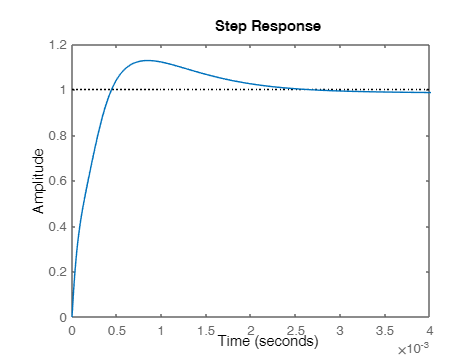


C = @(K) K(1) + ...
         K(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2))) + ...
         K(3)*((2*omega_c3*s)/((s^2) + (2*omega_c3*s) + ((3*omega_0)^2))) + ...
         K(4)*((2*omega_c5*s)/((s^2) + (2*omega_c5*s) + ((5*omega_0)^2))) + ...
         K(5)*((2*omega_c7*s)/((s^2) + (2*omega_c7*s) + ((7*omega_0)^2)));



G_cl = feedback(G*C(K),1);
step(G_cl)

function K = PRPH357tune(G,K0)

omega_0 = 2*pi*50;   % rad/sec
omega_c = 0.5;       % rad/sec
omega_c3 = 2.5;
omega_c5 = 4.5;
omega_c7 = 10;

s = tf('s');

% Umělý obdélníkový signál pro optimalizaci THD
fs = 50000*2*pi; % vzorkovací frekvence
f0 = 50*2*pi; % hlavní frekvence signálu
t = 0:(1/fs):(1/f0); % časový vektor
% Vytvoření základního sinusového signálu
x = sin(2*pi*f0*t);
% Přidání harmonického zkreslení
for n = 3:2:7
    x = x + ((1/n))*sin(2*pi*n*f0*t);
end

K_0 = [K0(1) K0(2)]; 

% Regulator:
C = @(K) K(1) + K(2)*((2*omega_c*s)/((s^2) + (2*omega_c*s) + (omega_0^2)));
% Close loop:
G_cl = @(K) feedback(G*C(K),1);

% Váhy jednotlivých kritérií objektivní funkce
W = [7 1 1 1];

% normalizace hodnot
normalization = [1000 0.1 50 0.1]; 
% Rise time: 1ms = 1, 
% Overshoot: 10% = 1 
% Transient time: 20ms = 1
% H - inf norma: 10 = 1 

% Objective function
obj = @(K)  W(1) * normalization(1) * (abs(stepinfo(G_cl(K)).RiseTime)) ... % doba náběhu
          + W(2) * normalization(2) * (abs(stepinfo(G_cl(K)).Overshoot)) ... % překmit
          + W(3) * normalization(3) * (abs(stepinfo(G_cl(K)).TransientTime)) ... % doba ustálení
          + W(4) * normalization(4) * (norm(G_cl(K),inf))... % Robustnost při vysokých frekvencích; stejne jako: max(abs(G))
          ... % + W(4) * (cond(ss(G_cl(K)).A)) ... % Robustnost při nízkých frekvencích   
            ;

% Condition function
nonlcon = @(K) mynonlcon(K,G_cl,x,t,fs,5);

% Ohraničení konstant K
lb = [0,0];
ub = [10000,10000];
options = optimoptions('fmincon','Display','iter','MaxIter',100,'TolFun',1e-12);
K1 = fmincon(obj,K_0,[],[],[],[],lb,ub,nonlcon,options);

Risetime = W(1) * normalization(1) * (abs(stepinfo(G_cl(K1)).RiseTime)) % doba náběhu
Overshoot = W(2) * normalization(2) * (abs(stepinfo(G_cl(K1)).Overshoot)) % překmit
Transienttime = W(3) * normalization(3) * (abs(stepinfo(G_cl(K1)).TransientTime)) % doba ustálení
Robustness = W(4) * normalization(4) * (norm(G_cl(K1),inf)) % Robustnost při vysokých frekvencích; stejne jako: max(abs(G))


% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 

G = feedback(G*C(K_0),1)

K_0 = [K0(3) K0(4) K0(5)];

% Regulator:
C = @(K) K(1)*((2*omega_c3*s)/((s^2) + (2*omega_c3*s) + ((3*omega_0)^2))) + ...
         K(2)*((2*omega_c5*s)/((s^2) + (2*omega_c5*s) + ((5*omega_0)^2))) + ...
         K(3)*((2*omega_c7*s)/((s^2) + (2*omega_c7*s) + ((7*omega_0)^2)));

% Close loop:
G_cl = @(K) feedback(G,C(K));

% Objective function
obj = @(K)  W(1) * normalization(1) * (abs(stepinfo(G_cl(K)).RiseTime)) ... % doba náběhu
          + W(2) * normalization(2) * (abs(stepinfo(G_cl(K)).Overshoot)) ... % překmit
          + W(3) * normalization(3) * (abs(stepinfo(G_cl(K)).TransientTime)) ... % doba ustálení
          + W(4) * normalization(4) * (norm(G_cl(K),inf))... % Robustnost při vysokých frekvencích; stejne jako: max(abs(G))
          ... % + W(4) * (cond(ss(G_cl(K)).A)) ... % Robustnost při nízkých frekvencích   
            ;


% Condition function
nonlcon = @(K) mynonlcon(K,G_cl,x,t,fs,3);

% Ohraničení konstant K
lb = [0,0,0];
ub = [10000,10000 10000];

G_cl(K_0)


options = optimoptions('fmincon','Display','iter','MaxIter',100,'TolFun',1e-12);
K2 = fmincon(obj,K_0,[],[],[],[],lb,ub,nonlcon,options);
% % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % % 

K = [K1 K2];

Risetime = W(1) * normalization(1) * (abs(stepinfo(G_cl(K)).RiseTime)) % doba náběhu
Overshoot = W(2) * normalization(2) * (abs(stepinfo(G_cl(K)).Overshoot)) % překmit
Transienttime = W(3) * normalization(3) * (abs(stepinfo(G_cl(K)).TransientTime)) % doba ustálení
Robustness = W(4) * normalization(4) * (norm(G_cl(K),inf)) % Robustnost při vysokých frekvencích; stejne jako: max(abs(G))
end


function thd = spectral_density(sys, x,  t, fs, n)
y = lsim(sys,x,t);
pxx = periodogram(y,[],length(x),fs);
pxx = 100*(pxx)/(max(pxx)); % normalizace hodnot na procenta

thd = 0;
for nn = n
    thd = thd + pxx(nn);
end
end

function [c,ceq] = mynonlcon(K,G_cl,x,t,fs,h)
c = spectral_density(G_cl(K),x,t,fs,4:2:8) - h;           
ceq = [];
end
